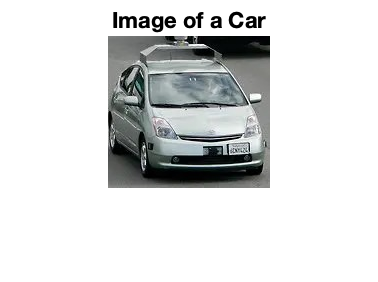

carImage = imread('/Users/bhargavmuppalla/Documents/Computer Vison/HW3/car.jpeg');
figure;
imshow(carImage);
title('Image of a Car');

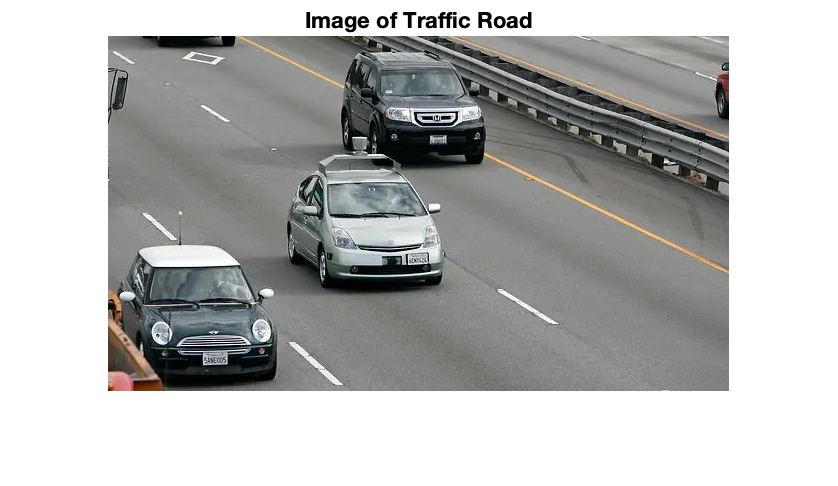


sceneImage = imread('/Users/bhargavmuppalla/Documents/Computer Vison/HW3/scence.jpeg');
figure;
imshow(sceneImage);
title('Image of Traffic Road');

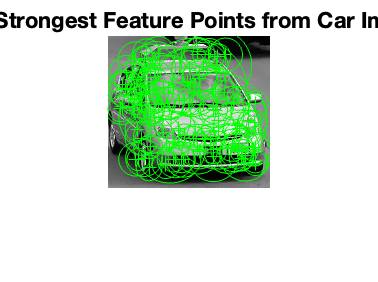


carImage = rgb2gray(carImage);
sceneImage = rgb2gray(sceneImage);

carPoints = detectSURFFeatures(carImage);
scenePoints = detectSURFFeatures(sceneImage);

figure;
imshow(carImage);
title('100 Strongest Feature Points from Car Image');
hold on;
plot(selectStrongest(carPoints, 100));

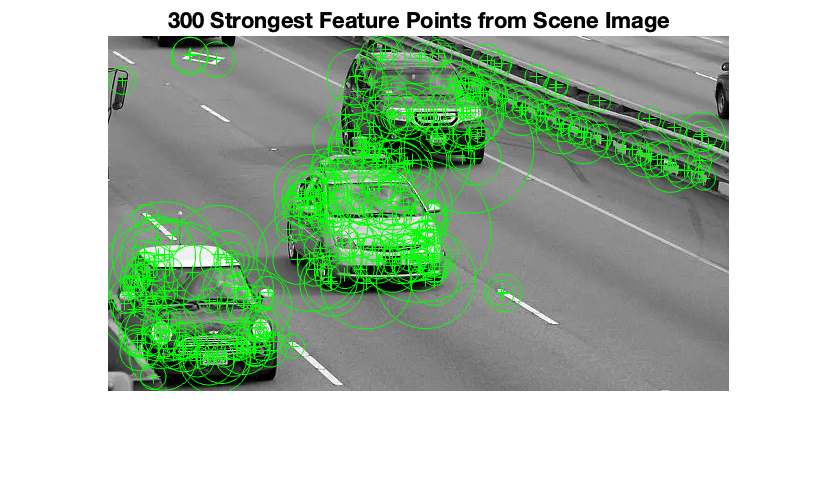


figure;
imshow(sceneImage);
title('300 Strongest Feature Points from Scene Image');
hold on;
plot(selectStrongest(scenePoints, 300));

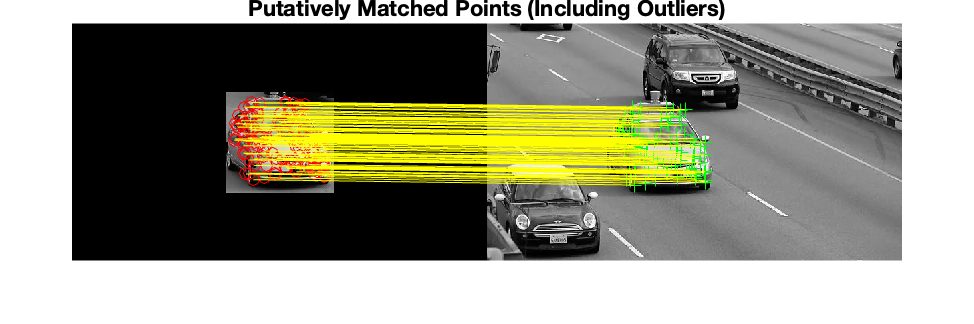


[carFeatures, carPoints] = extractFeatures(carImage, carPoints);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

carPairs = matchFeatures(carFeatures, sceneFeatures);

matchedCarPoints = carPoints(carPairs(:, 1), :);
matchedScenePoints = scenePoints(carPairs(:, 2), :);
figure;
showMatchedFeatures(carImage, sceneImage, matchedCarPoints, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

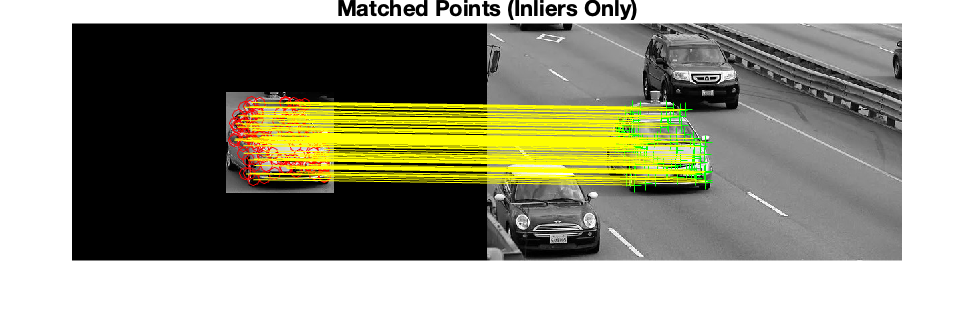

[tform, inlierIdx] = ...
    estimateGeometricTransform2D(matchedCarPoints, matchedScenePoints, 'affine');
inlierCarPoints   = matchedCarPoints(inlierIdx, :);
inlierScenePoints = matchedScenePoints(inlierIdx, :);

figure;
showMatchedFeatures(carImage, sceneImage, inlierCarPoints, ...
    inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

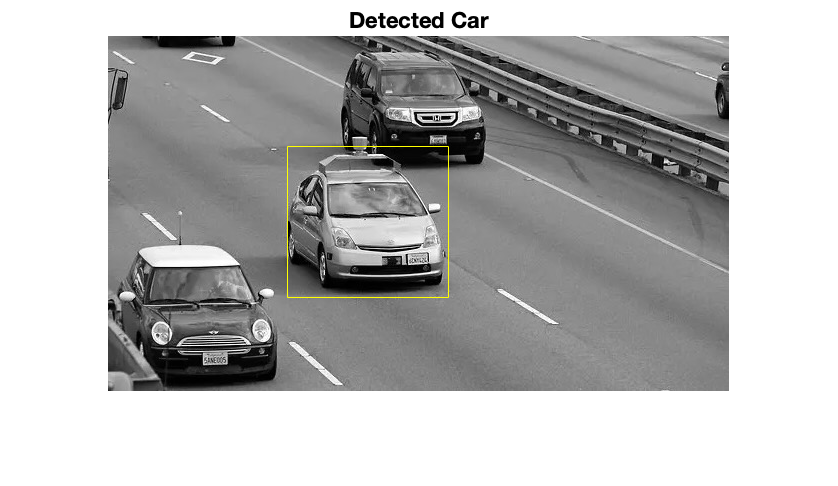


carPolygon = [1, 1;...                           % top-left
        size(carImage, 2), 1;...                 % top-right
        size(carImage, 2), size(carImage, 1);... % bottom-right
        1, size(carImage, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon

newCarPolygon = transformPointsForward(tform, carPolygon);

figure;
imshow(sceneImage);
hold on;
line(newCarPolygon(:, 1), newCarPolygon(:, 2), 'Color', 'y');
title('Detected Car');